# 重心の計算

clear
close all
clc


% *** 実験実習で測定計測したデータ を load***
fileName = 'Data_S02' ; % ←　被験者番号を指定する
load(fileName) ;

Data = DataStruct.CMJ(1) ; % ←　条件名・試行番号を指定する
grfs = Data.Forces ;
Markers = Data.Markers ;
cop = Data.CoP ;
% ****


% マーカー名の確認
MarkerNames = fieldnames(Markers)

MarkerNames = 6×1 の cell 配列
    {'Hip'     }
    {'Knee'    }
    {'Toe'     }
    {'Ankle'   }
    {'Heel'    }
    {'Shoulder'}


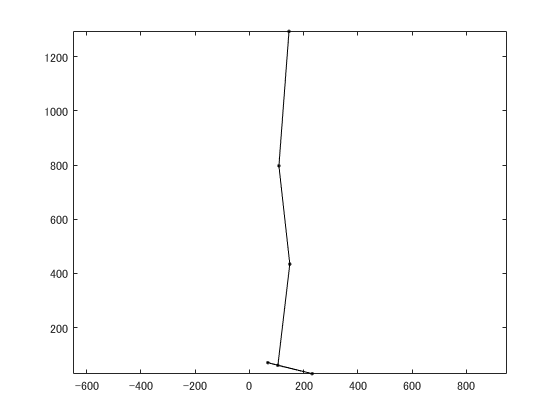


% マーカー位置のプロット
figure
iFrame = 1 ;
MarkerNames = {'Shoulder', 'Hip', 'Knee', 'Ankle', 'Toe', 'Heel', 'Ankle'} ;
stickPicture(Markers, MarkerNames, iFrame, 'yz', 'k.-') ;
axis equal

人体計測データは、Winter （2009）を参照のこと

日本語版では、p.86 

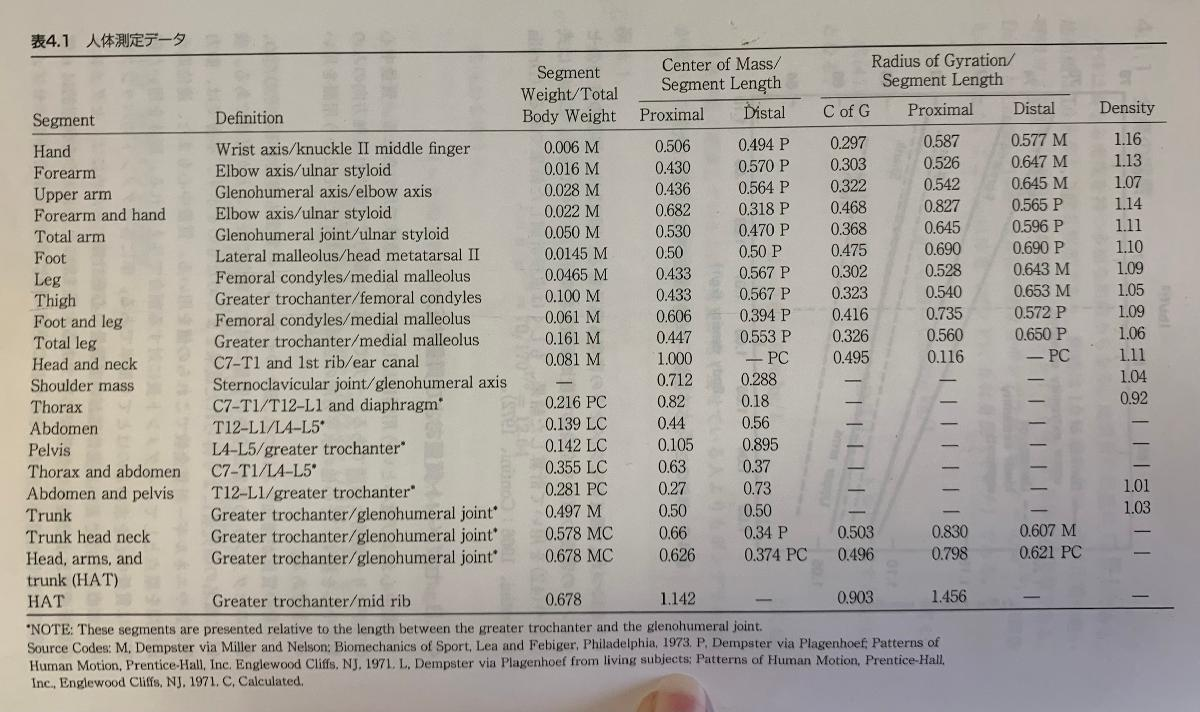


% セグメント重心

% Head-Arms-and-Trunk セグメントのセグメント重心は、大転子と肩のマーカー位置を、0.626:0.374 に内分した点にある
Segments.HAT = 0.374 * Markers.Hip + 0.626 * Markers.Shoulder ; 


% ///// 同様に、Thigh, Leg, Foot セグメントのセグメント重心位置を計算してください /////
% /////　それぞれ、 Segments.Thigh, Segments.Leg, Segments.Foot とし、 構造体にまとめてください /////





首尾よく計算できていたなら、こんな感じのプロットが書けるはずです

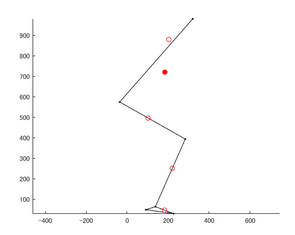

% 身体重心
Segments.CoM = Segments.HAT * 0.678 + Segments.Thigh * 0.1 * 2 + ...
               Segments.Leg * 0.0465 * 2 + Segments.Foot * 0.0145 * 2 ;

存在しないフィールド 'Thigh' を参照しています。



% セグメント重心位置のプロット
figure ; hold on 
iFrame = 1 ;
MarkerNames = {'Shoulder', 'Hip', 'Knee', 'Ankle', 'Toe', 'Heel', 'Ankle'} ;
stickPicture(Markers, MarkerNames, iFrame, 'yz', 'k.-') ; 
SegmentNames = {'HAT', 'Thigh', 'Leg', 'Foot'} ;
stickPicture(Segments, SegmentNames, iFrame, 'yz', 'ro') ;
SegmentNames = {'CoM'} ;
stickPicture(Segments, SegmentNames, iFrame, 'yz', 'ro', 'markerfacecolor', 'r') ;

axis equal

